# Introduction to Interactive Learning

**Michele Ferrari [*****21118273*****]**

**21/11/2021**

## Introduction

Interactive Machine Learning is a branch of Machine Learning in which the user takes part in the training phase. He is not limited anymore to simply providing the machine with a set of training samples and labels, but he can also act as a labeling oracle for each iteration of the learning process.

Here, three different approaches are implemented:

- ***Computer-Initiated***, where an active learning algorithm picks a query $x$ and the human answers its label $y$, 

- ***Human-Initiated***, where the human picks $x$ and $y$,

- ***Mixed-Initiative***, where both parties can pick $x$.

Moreover, different types of human oracles exist, ranging from very efficient to completely random ones (as described in [1]):

- **Optimal teacher**, that provides a optimal teaching set,

- **Seed teacher**, when the teacher is not optimal but can provide at least one item for each class,

- **Naive teacher**, when the teacher is not able to wisely choose labels and simply performs a random choice (which can also be detrimental).

In **Table 1**, it can be seen how different types of teachers can impact on the performance of the three different approaches. Referring to [1] for a detailed explanation, we simply remark that the C*omputer-Initiated* approach is not influenced by the type of human agent, whereas the other two approaches benefit in general from having a teacher that can provide labels more efficiently.

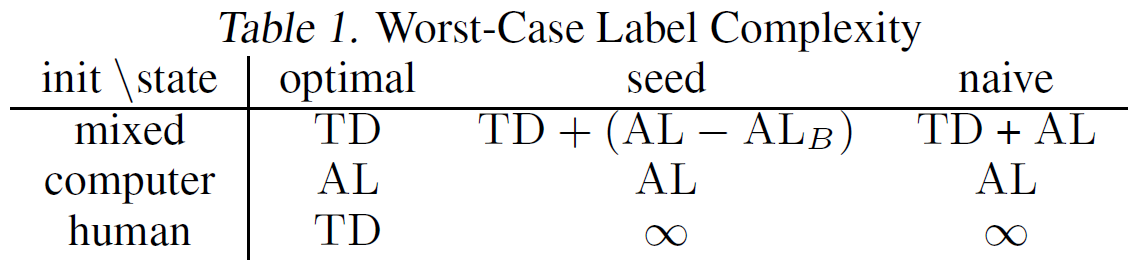

**Table 1:** Impact of the kind of teacher on the performance for every approach [1].

In this work, the different kind of teacher are simulated thanks to a class defined on purpose (`Human_agent`), but the user is also allowed to manually input items and labels. Furthermore, the simulated teacher can be either infallible or fallible, meaning that the code can deal also with situations in which labelization errors occur.

Finally, the class `Human_agent` is also dedigned to deal with probabilistic labels, however the three approaches have been implemented considering binary labels ($P\left({\textrm{label}}_i ={\textrm{class}}_j \right)=1\;\textrm{or}\;0$), that here are indicated as either "Positive" or "Negative".

[1] *Jina Suh, Xiaojin Zhu, Saleema Amershi ; Proceedings of The 33rd International Conference on Machine Learning, PMLR 48 :2800-2809, 2016.*

## 1. Parameter Definition & Problem Setting

Algorithms are tested using a fixed threshold towards which they have to converge. In this case, the input space ranges from 0 to 1, the true threshold is 0.65 and the tolerance band is 0.02 wide. Classes are labeled as follows:

- "Positive" if $\mathrm{input}\ge \mathrm{true}\_\mathrm{threshold}$,

- "Negative" if $\mathrm{input}<\mathrm{true}\_\mathrm{threshold}$.

clear; close all; clc

input_space = [0 1];
tolerance = 0.01;

delta_input = input_space(2)/10;

true_threshold = 0.65;
certainty_mu = 0.8;
certainty_sigma = 0.1;

## 2. Human Agent Class Definition

Select the type of human teacher among four different options:

- optimal teacher

- seed teacher

- naive teacher

- manual teacher (inputs are provided by an actual user typing $x$ values and labels)

response_flag = "Infallible";
optimality_flag = "Seed";

**N.B.:** 

- `response_flag` has to be set to *Manual*, if `optimality_flag` is set to *Manual*, and viceversa.

- `optimality_flag` only makes sense in the *Human-Initiated* and *Mixed-Initiative* approaches

% Create the teacher
deterministic = true;
teacher = Human_agent(response_flag,optimality_flag,deterministic,true_threshold,certainty_mu,certainty_sigma);

## 3. Computer-initiated Approach

### 3.1 Algorithm Description

In the *Computer-initiated* approach, *Active Learning* (AL) is performed until convergence is achieved. In this case, convergence is attained when the absolute error between the true threshold and the computed one is smaller than a given tolerance.

AL consists in the choice of an item $x_i$ for each iteration $i$ based on previous pairs of items and labels $\left(x_1 ,y_1 \right),\;\ldotp \ldotp \ldotp \;\left(x_{i-1} ,y_{i-1} \right)$ (step 1). The user is then presented with this value of $x_i$, to which he has to assign a label $y_i$ (step 2). Therefore the human acts as a *labeling oracle*.

In the code below, the function `provide_input_computer` performs step 1, whereas the method `teacher_response` of the object `teacher` of type `Human_agent` performs step 2, according to the kind of human agent (either fallible or infallible).

Step 1 can be implemented using different algorithms, in this case the *bisection method* has been applied.

The following algorithm allows also for a manual execution of both steps.

### 3.2 Algorithm Implementation

% Initialize variables to hold results
initialization
iter_error = Inf;

while iter_error > tolerance
    x = provide_input_computer(inputs,labels,input_space(1),input_space(2));
    if strcmp(response_flag,'Manual')
        message = sprintf("Value: %f", x);
        uiwait(msgbox(message));
    end
    label_prob = teacher_response(teacher,x);

    % Assign a label, given the label probability P(label == 'Positive')
    labels = label_prob_2_label(label_prob,labels);

    prev_x = x;
    iter = iter+1;
    inputs = [inputs; x];
    label_probs = [label_probs; label_prob];
    iters = [iters; iter];

    % Check convergence
    idx_pos = contains(labels,"Positive");
    idx_neg = contains(labels,"Negative");
    min_pos = min(inputs(idx_pos));
    max_neg = max(inputs(idx_neg));

    if ~isempty(find(idx_pos)) && ~isempty(find(idx_neg)) %#ok<EFIND> 
        thresh = (min_pos+max_neg)/2;
        iter_error = abs(thresh-true_threshold);
    end   

    thresholds = [thresholds; thresh];
    iter_errors = [iter_errors; iter_error];

    % Check feasibility (not guaranteed if the teacher is fallible)
    if min_pos < max_neg
       disp("Failure! Values belonging to 'Negative' cannot be greater than values belonging to 'Positive'.")
       failure = true;
       break
    end

end

% Create a structure to gather results, to be saved in the results folder
metrics.labels = labels;
metrics.iters = iters;
metrics.inputs = inputs;
metrics.label_probabilities = label_probs;
metrics.thresholds = thresholds;
metrics.iter_errors = iter_errors;
metrics.failure = failure;

save(strcat('.\results\','ComputerInit_',response_flag,'_',optimality_flag,'.mat'),'metrics')

### 3.3 Plot Results

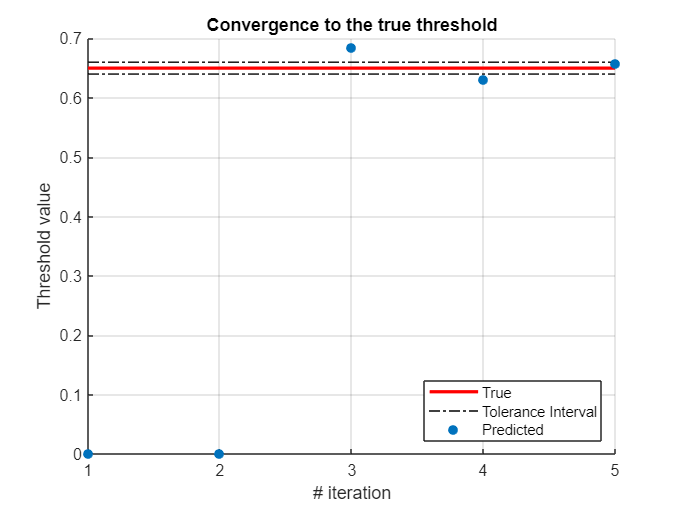

plot_results(thresholds,true_threshold,tolerance)

## 4. Human-initiated Approach

### 4.1 Algorithm Description

In the *Human-initiated* approach, the human can choose any item $x_i$ for each iteration $i$ (the choice depends on its degree of optimality). The human can decide how many iterations to teach, based on its level of confidence in the model (threshold) learned by the machine. Since in this simulation the threshold is known (not generally true in real applications), the learning process is stopped when convergence is attained.

To be more rigorous, the quantity TD can be defined as in **Definition 3** below:

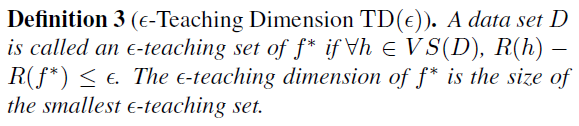

Hence, the automatic algorithm will allow the user to input up to TD item, which are sufficient to guarantee the convergence of the method.

In the code below, the method `teacher_input` provides the machine with the input according to the kind of human agent (optimal, seed, naive,...), whereas the method `teacher_response` provides the machine with the label (exact or with a certain margin of error).

The following algorithm allows also for a manual execution of both steps.

### 4.2 Algorithm Implementation

In this case, it makes no sense distinguishing among different types of teachers. We can only simulate teachers that can or cannot miss the labelization, but we cannot specify their degree of optimality.

% Initialize variables to hold results
initialization

prev_x = input_space(1); % Arbitrary previous input
iter_error = abs(thresh-true_threshold);

while iter_error > tolerance
    [x,teacher] = teacher_input(teacher,input_space(1),input_space(2),delta_input,prev_x);
    label_prob = teacher_response(teacher,x);

    % Assign a label, given the label probability P(label == 'Positive')
    labels = label_prob_2_label(label_prob,labels);

    prev_x = x;
    iter = iter+1;
    inputs = [inputs; x];
    label_probs = [label_probs; label_prob];
    iters = [iters; iter];

    % Check convergence
    idx_pos = contains(labels,"Positive");
    idx_neg = contains(labels,"Negative");
    min_pos = min(inputs(idx_pos));
    max_neg = max(inputs(idx_neg));

    if ~isempty(find(idx_pos)) && ~isempty(find(idx_neg)) %#ok<EFIND> 
        thresh = (min_pos+max_neg)/2;
        iter_error = abs(thresh-true_threshold);
    end

    thresholds = [thresholds; thresh];
    iter_errors = [iter_errors; iter_error];

    % Check feasibility (not guaranteed if the teacher is fallible)
    if min_pos < max_neg
       disp("Failure! Values belonging to 'Negative' cannot be greater than values belonging to 'Positive'.")
       failure = true;
       break
    end

end

% Create a structure to gather results, to be saved in the results folder
metrics.labels = labels;
metrics.iters = iters;
metrics.inputs = inputs;
metrics.label_probabilities = label_probs;
metrics.thresholds = thresholds;
metrics.iter_errors = iter_errors;
metrics.failure = failure;

save(strcat('.\results\','HumanInit_',response_flag,'_',optimality_flag,'.mat'),'metrics')


### 4.3 Plot Results

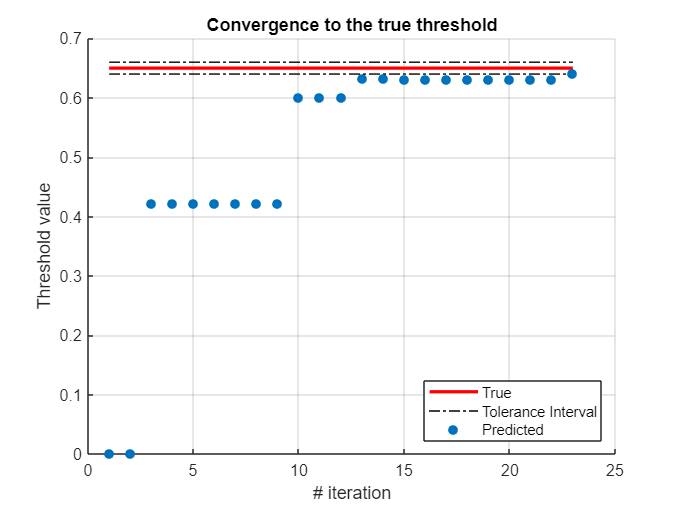

plot_results(thresholds,true_threshold,tolerance)

## 5. Mixed-initiative Approach

### 5.1 Algorithm Description

This approach is a combination of the previous ones, since it consists in two main phases:

- In the beginning, the human can provide a certain number of labeled items $\left(x_i ,y_i \right)$,

- Then the machine starts AL exploiting the data the human agent provided in the first phase. In this second phase the human acts as labeling oracle.

The algorithm runs until convergence is attained.

The pseudo-code for this mechanism can be seen in Fig.1.

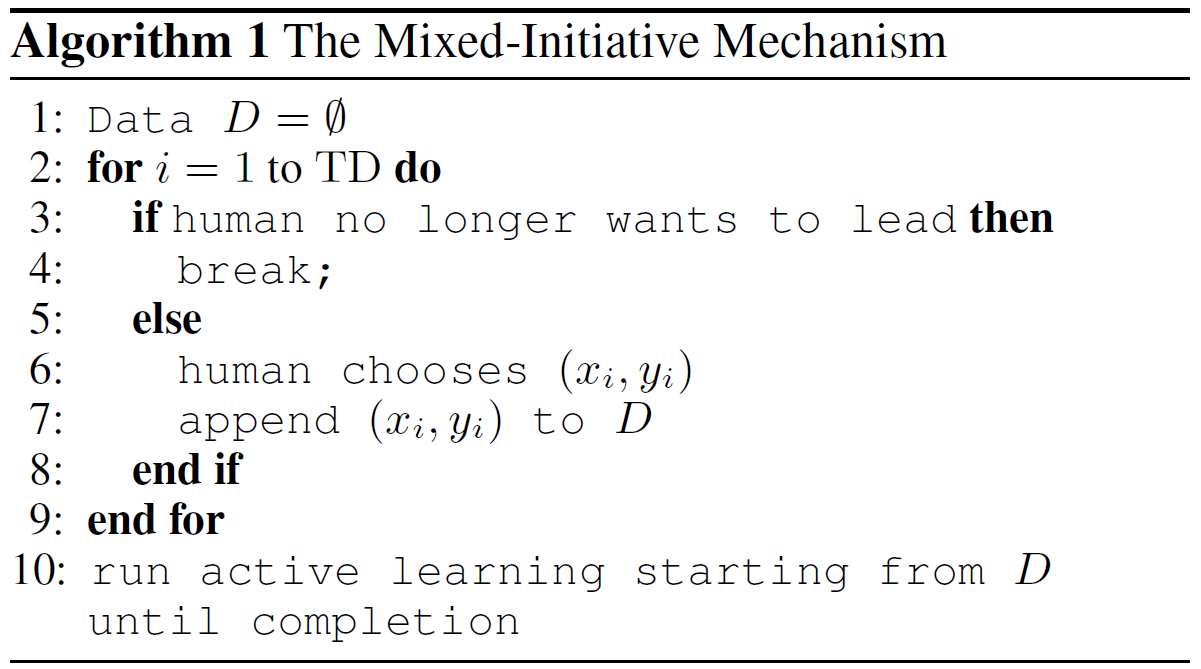

**Fig.1:** *Mixed-Initiative* approach, pseudocode taken from [1].

As a final remark, in the case of the optimal teacher, after the first phase the training samples allow to determine the correct threshold, without even running AL. That is because an optimal teacher provides exactly TD items (see Definition 3), which are already sufficent to guarantee the convergence of the algorithm.

### 5.2 Algorithm Implementation

% Initialize variables to hold results
initialization

prev_x = input_space(1); % Arbitrary previous input
iter_error = abs(thresh-true_threshold);

numIter_human = 5; % Number of (input,label) pairs provided by the human teacher before starting active learning

while iter_error > tolerance
    if iter < numIter_human
        [x,teacher] = teacher_input(teacher,input_space(1),input_space(2),delta_input,prev_x);
    else
        x = provide_input_computer(inputs,labels,input_space(1),input_space(2));
    end

    label_prob = teacher_response(teacher,x);

    % Assign a label, given the label probability P(label == 'Positive')
    labels = label_prob_2_label(label_prob,labels);

    prev_x = x;
    iter = iter+1;
    inputs = [inputs; x];
    label_probs = [label_probs; label_prob];
    iters = [iters; iter];

    % Check convergence
    idx_pos = contains(labels,"Positive");
    idx_neg = contains(labels,"Negative");
    min_pos = min(inputs(idx_pos));
    max_neg = max(inputs(idx_neg));

    if ~isempty(find(idx_pos)) && ~isempty(find(idx_neg)) %#ok<EFIND> 
        thresh = (min_pos+max_neg)/2;
        iter_error = abs(thresh-true_threshold);
    end

    thresholds = [thresholds; thresh];
    iter_errors = [iter_errors; iter_error];

    % Check feasibility (not guaranteed if the teacher is fallible)
    if min_pos < max_neg
       disp("Failure! Values belonging to 'Negative' cannot be greater than values belonging to 'Positive'.")
       failure = true;
       break
    end

end

% Create a structure to gather results, to be saved in the results folder
metrics.labels = labels;
metrics.iters = iters;
metrics.inputs = inputs;
metrics.label_probabilities = label_probs;
metrics.thresholds = thresholds;
metrics.iter_errors = iter_errors;
metrics.failure = failure;

save(strcat('.\results\','MixedInit_',response_flag,'_',optimality_flag,'.mat'),'metrics')

### 5.3 Plot Results

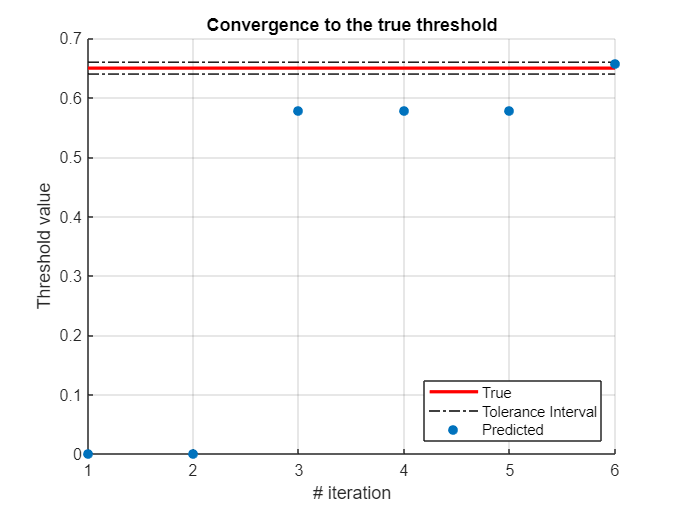

plot_results(thresholds,true_threshold,tolerance)

## 6. Practical Application with Unknown Threshold: Cats vs Dogs

In order to apply this reasoning to a more practical example, the problem of classifying a given image as "Dog" or "Cat" is tackled. In this approach, the machine asks the user to label training samples and extracts from them features, based on which it can determine the boundary between the two classes. In this application, as in real-world, the threshold is not even known to the labeling oracle (who cannot know the value of each feature that exactly separates two classes).

The user can select to stop or continue the training phase anytime, depending on how satisfied he is with the classification accuracy (computed on a given test dataset).

This method is clearly *Human-Initiated.*

*Since we are only interested in developing a framework to make this algorithm work, only few training samples are provided to the user. In reality, a much larger training set is required, if we want to obtain a robust model that can be better generalized to unknown test samples.*

### 6.1 Load Data

load_datasets

response_flag = "Manual";
optimality_flag = "Manual";

### 6.2 Plot Training Dataset

figure
set(gcf,'Visible','on')
tiledlayout(floor(sqrt(2*nSamples_train)),ceil(sqrt(2*nSamples_train)));

for i = 1:2*nSamples_train
    nexttile
    imshow(train{i})
end

### 6.3 Tuning of the Feature Extractor

HOG (Histogram of Oriented Gradients) features are extracted, after a **preprocessing phase** in which the image is masked.

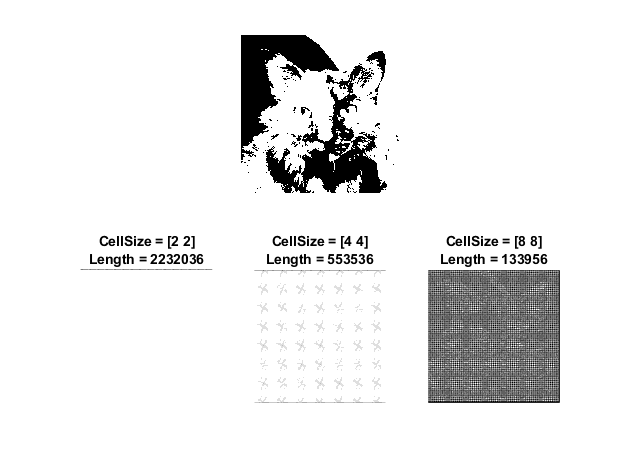

% Feature Vector Example
processedImage = imbinarize(im2gray(train{1}));

% Extract HOG features and HOG visualization
[hog_2x2, vis2x2] = extractHOGFeatures(processedImage,'CellSize',[2 2]);
[hog_4x4, vis4x4] = extractHOGFeatures(processedImage,'CellSize',[4 4]);
[hog_8x8, vis8x8] = extractHOGFeatures(processedImage,'CellSize',[8 8]);

% Show the original image
figure; 
subplot(2,3,1:3); imshow(processedImage);

% Visualize the HOG features
subplot(2,3,4);  
plot(vis2x2); 
title({'CellSize = [2 2]'; ['Length = ' num2str(length(hog_2x2))]});

subplot(2,3,5);
plot(vis4x4); 
title({'CellSize = [4 4]'; ['Length = ' num2str(length(hog_4x4))]});

subplot(2,3,6);
plot(vis8x8); 
title({'CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

### 6.4 Extract Features for Test Set

% Extract Test Features
features_test = [];
for i = 1:2*nSamples_test
    processedImage = imbinarize(im2gray(test{i}));
    [new_features,~] = extractHOGFeatures(processedImage,'CellSize',[4 4]);
    features_test = [features_test; new_features];
end

### 6.5 Perform Interactive Learning

After each iteration, a SVM (Support Vector Machine) model is trained, based on the current and all previous training samples. The hyperplane that separates the two classes is updated every iteration, so that the threshold between the two classes can be better and better identified.

inputs = {};
label_probs = [];
labels = [];
features = [];

for i = 1:2*nSamples_train
    figure
    set(gcf,'Visible','on')
    image(train{i})
    axis equal

    answer = questdlg('To which class does the current sample belong?', ...
                            'Sample Labelization', ...
                            'Cat','Dog','Cat');
    close

    switch answer
        case 'Cat'
            label_prob = 1; % P(label == 'Cat')
        case 'Dog'
            label_prob = 0;
    end

    processedImage = imbinarize(im2gray(train{i}));
    [new_features,hogVisualization] = extractHOGFeatures(processedImage,'CellSize',[4 4]);

    inputs = [inputs; train{i}];
    label_probs = [label_probs; label_prob];
    labels = [labels; string(answer)];
    features = [features; new_features];

    idx_pos = contains(labels,"Cat");
    idx_neg = contains(labels,"Dog");

    if ~isempty(find(idx_pos)) && ~isempty(find(idx_neg)) %#ok<EFIND> 
        classifier = fitcecoc(features, labels);

        label_predicted = predict(classifier, features_test);
        figure
        set(gcf,'Visible','on')
        confMat = confusionchart(label_test,label_predicted,'RowSummary','row-normalized','ColumnSummary','column-normalized');
        title('Test Confusion Matrix')
        pause(2)
        close

        if i ~= 2*nSamples_train
            answer = questdlg('Continue Training?', ...
                              'Continue', ...
                              'Yes','No','Yes');
            close
            switch answer
                case 'Yes'
                    continue
                case 'No'
                    break
            end
        end 

    end
end

Final Confusion Matrix:

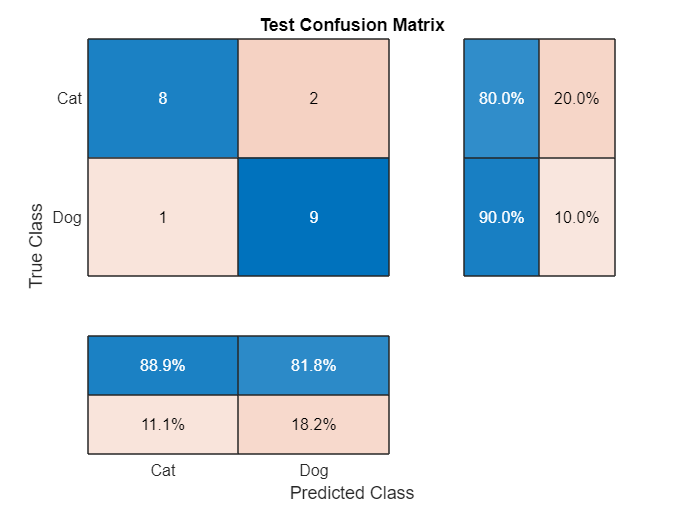

figure
confMat = confusionchart(label_test,label_predicted,'RowSummary','row-normalized','ColumnSummary','column-normalized');
title('Test Confusion Matrix')

## Conclusion

Running the code multiple times, according to the possible different combinations of the parameters defining the human teacher:

- (Optimal, Infallible) teacher,

- (Optimal, Fallible) teacher,

- (Seed, Infallible) teacher,

- (Seed, Fallible) teacher,

- (Naive, Infallible) teacher,

- (Naive, Fallible) teacher,

- Manual teacher,

we can see the difference that the optimality of the teacher can make on the performance of the algorithm.

Moreover, if the teacher can provide wrong labels, the algorithms are not even guaranteed to converge, leading to a failure of the teaching process.